## Problem 2.83 for 2.34(b)

Repeat Problem 2.34(b), using MATLAB conv command. 

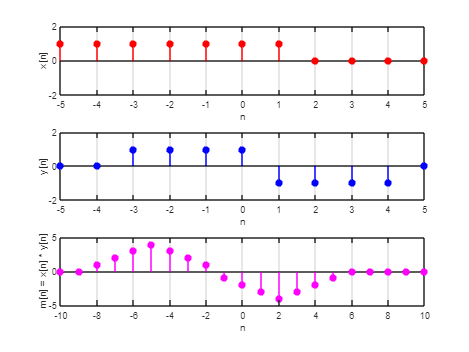

n = -5:5;
x = zeros(size(n));

x(n==-5)  = 1; x(n==-4) = 1; x(n==-3) = 1; x(n==-2) = 1; x(n==-1) = 1; x(n== 0) = 1; x(n== 1) = 1;

subplot(3, 1, 1);
stem(n, x, 'filled','Color','r')
ylim([-2 2])
xlabel('n')
ylabel('x[n]')
grid on

y = zeros(size(n));

y(n==-3) = 1; y(n==-2) = 1; y(n==-1) = 1; y(n==0) = 1; y(n==1) = -1; y(n== 0) = 1; y(n== 1) = -1; y(n== 2) = -1; y(n== 3) = -1; y(n== 4) = -1;

subplot(3, 1, 2);
stem(n, y, 'filled','Color','b')
ylim([-2 2])
xlabel('n')
ylabel('y[n]')
grid on

subplot(3, 1, 3);
m = conv(x, y);
n_convoluted = (n(1) + n(1)) : (n(end) + n(end));
stem(n_convoluted, m, 'filled','Color','m')
xlabel('n')
ylabel('m[n] = x[n] * y[n]')
grid on


% This is what m is in variables... 
% 0	0	1	2	3	4	3	2	1	-1	-2	-3	-4	-3	-2	-1	0	0	0	0	0
% Which equates to ... 
% m[n] =     δ[n+8] + 2δ[n+7] + 3δ[n+6]  
%         + 4δ[n+5] + 3δ[n+4] + 2δ[n+3] 
%         -  δ[n+2] -  δ[n+1] - 2δ[n]    
%         - 3δ[n-1] - 4δ[n-2] - 3δ[n-3] 
%         + 2δ[n-4] -  δ[n-5]
% Which matches the graph!